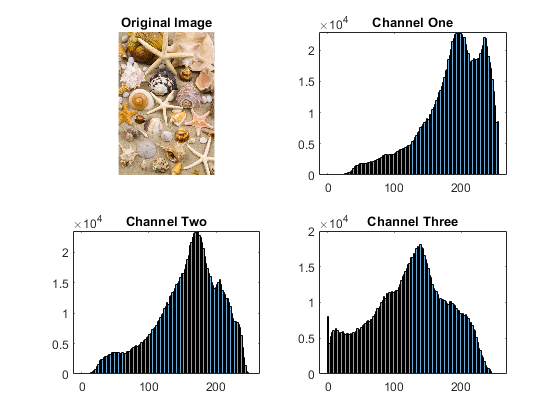

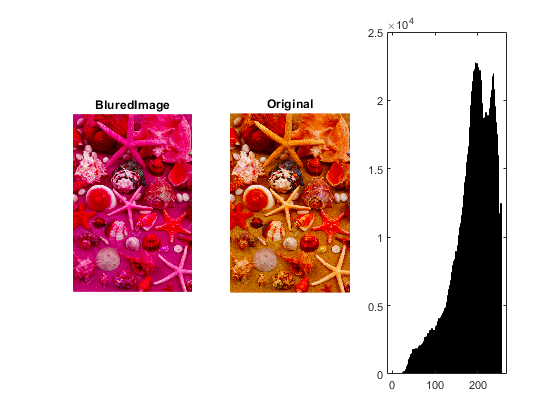

Taking Blue Channel


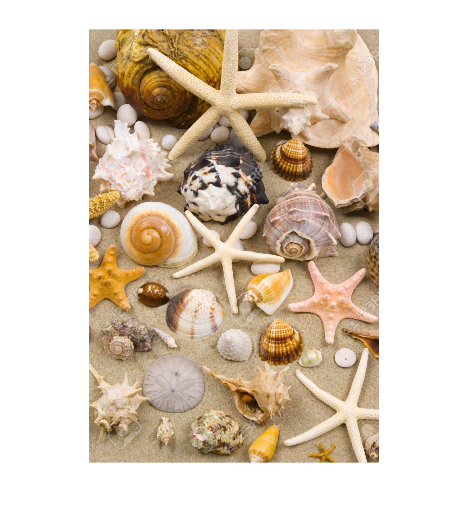

1: BoudningBox:  X: 838.5 Y: 820.5 Eccentricity: 0.60232 Solidity: 0.65499 Area: 243
2: BoudningBox:  X: 321.5 Y: 932.5 Eccentricity: 0.71963 Solidity: 0.5631 Area: 589


Taking Blue Channel


%See output for all files
workingFiles = dir(fullfile("./workingImages", '*.jpg'));
for image = 1:size(workingFiles)
    fileLocation = workingFiles(image).folder + "/" + workingFiles(image).name;
    [boundingBox, count] = masterPipeline(fileLocation);
    sizeOfBoudingBox = size(boundingBox);
output = figure;
imshow(LoadImage(fileLocation));
hold on;
for x = 1:sizeOfBoudingBox(1)
    
  thisBB = boundingBox(x, (1:4));
  text(thisBB(1) + thisBB(3) /2, thisBB(2) - 10,"" + x);
  rectangle('Position', [thisBB(1),thisBB(2),thisBB(3),thisBB(4)],'EdgeColor','r','LineWidth', 2);
    

end
hold off;
title("Final Output: There are " + count + " Starfish");

mkdir("./" + count + "/");
saveas(output, "./" + count + "/" + workingFiles(image).name);
end